# Temporary: for XLRED summary

% input 
clear
clc
dirpath = 'D:\OneDrive - rice.edu\Francois\RedGEVIs\Wet\Results';
fName = '20200102 Summary of XLREDs.xlsx';
template = 'JEDI-1P::cpmOrange';
sheet = {'174-1-173-1','172-1-171'};
controlName = ['ASAP1','JEDI-1P','JEDI-1P-VSD-N-1-C-1-cpmOrange2-174-173','JEDI-1P-cpmOrange2-172-1-171-1'];


% load data
libOrange = struct;
for i = 1:length(sheet)
    libOrange(i).parent = strcat(template,sheet(i));
    libOrange(i).data = readtable(fullfile(dirpath,fName),'Sheet',sheet{i});
    % Trim table
    ActSize = sum(~isnan(libOrange(i).data.RatioOfMeanBrightness_C2_C3_));
    libOrange(i).data([ActSize+1:end],:) = [];
end

% parse libraries
for i = 1:length(sheet)
    for w = 1:height(libOrange(i).data)
        parsename = split(libOrange(i).data.Name{w},["_",'(',')']);
        libOrange(i).data.PlateWell{w} = parsename{end-1};
        libOrange(i).data.Parent{w} = parsename{1};
        if length(parsename) == 3
            libOrange(i).data.ScreenPos{w} = '';
            libOrange(i).data.VarName{w} = parsename{1};
        else
            libOrange(i).data.ScreenPos{w} = parsename{2};
            libOrange(i).data.VarName{w} = strcat(parsename{1},'_',libOrange(i).data.ScreenPos{w});
        end
        
    end
end

% plot by library
ctrlcolor = [1 0 0; 0 0 1];
i = 1; % Sheet 1
figure()
hold on
LibPos = unique(libOrange(i).data.VarName);
libsel = [4:8]; 
ctrlsel = 3;
maxB = 0;
selrange = [];
for l = 1:length(libsel)
    librange = find(cellfun(@(x)~isempty(strfind(x,LibPos{libsel(l)})), libOrange(i).data.VarName));
    scatter(libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(librange),libOrange(i).data.Normalized20ms(librange),'filled','MarkerFaceAlpha',0.5);
    maxB = max(maxB,max(libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(librange)));
    selrange = [selrange;librange];
end

for c = 1:length(ctrlsel)
    ctrlrange = find(cellfun(@(x)~isempty(strfind(x,LibPos{ctrlsel(c)})), libOrange(i).data.VarName));
    plot(libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange),libOrange(i).data.Normalized20ms(ctrlrange),'rx','MarkerSize',15);
    maxB = max(maxB,max(libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange)));
    selrange = [selrange;ctrlrange];
end

x = 0:0.1:maxB+0.5;
DI1 = 1./sqrt(x);
DI2 = 2./sqrt(x);
plot(x,DI1,'--k')
plot(x,DI2,'-.k')
legend(LibPos([libsel,ctrlsel]))
xlabel('Normalized relative brightness (R/B)')
ylabel('Normalized response amplitude (dF/F0)')
axis([0,maxB+0.5,0,inf])

figure()
hold on
Normdff0 = libOrange(i).data.Normalized20ms(selrange);
Normdff0 = Normdff0(Normdff0>=0);
bar(sort(Normdff0,'ascend'))
xlabel('Number of construct screened')
ylabel('Normalized response amplitude (dF/F0)')

figure()
hold on
NormBr = libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(selrange);
NormBr = NormBr(NormBr>=0);
bar(sort(NormBr,'ascend'),'r','FaceAlpha',0.5)
xlabel('Number of construct screened')
ylabel('Normalized relative brightness (R/B)')

% plot by library
i = 2; % Sheet 1
figure()
hold on
LibPos = unique(libOrange(i).data.VarName);
libsel = [4:7]; 
ctrlsel = [2,3];
selrange = [];

for l = 1:length(libsel)
    librange = find(cellfun(@(x)~isempty(strfind(x,LibPos{libsel(l)})), libOrange(i).data.VarName));
    scatter(libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(librange),libOrange(i).data.Normalized20ms(librange),'filled','MarkerFaceAlpha',0.5);
    maxB = max(maxB,max(libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(librange)));
    selrange = [selrange;librange];
end
for c = 1:length(ctrlsel)
    ctrlrange = find(cellfun(@(x)~isempty(strfind(x,LibPos{ctrlsel(c)})), libOrange(i).data.VarName));
    plot(libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange),libOrange(i).data.Normalized20ms(ctrlrange),'x','MarkerSize',15,'Color',ctrlcolor(c,:));
    maxB = max(maxB,max(libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange)));
    selrange = [selrange;ctrlrange];
end

x = 0:0.1:maxB;
DI1 = 1./sqrt(x);
DI2 = 2./sqrt(x);
plot(x,DI1,'--k')
plot(x,DI2,'-.k')
legend(LibPos([libsel,ctrlsel]))
xlabel('Normalized relative brightness (R/B)')
ylabel('Normalized response amplitude (dF/F0)')
axis([0,maxB+0.5,0,inf])

figure()
hold on
Normdff0 = libOrange(i).data.Normalized20ms(selrange);
Normdff0 = Normdff0(Normdff0>=0);
bar(sort(Normdff0,'ascend'))
xlabel('Number of construct screened')
ylabel('Normalized response amplitude (dF/F0)')

figure()
hold on
NormBr = libOrange(i).data.NormalizedBrightness_Ch2_Ch3_(selrange);
NormBr = NormBr(NormBr>=0);
bar(sort(NormBr,'ascend'),'r','FaceAlpha',0.5)
xlabel('Number of construct screened')
ylabel('Normalized relative brightness (R/B)')

## Load data for mApple

template = 'JEDI-1P::cpmAppleGRAB';
sheet = {'mAppleGRAB','mAppleGRAB combine'};
controlName = ['ASAP1','JEDI-1P','JEDI-1P-cpmAppleGRAB ','JEDI-1P-cpmAppleGRAB_L392S'];
libApple = struct;
for i = 1:length(sheet)
    libApple(i).parent = strcat(template,sheet(i));
    libApple(i).data = readtable(fullfile(dirpath,fName),'Sheet',sheet{i});
    % Trim table
    ActSize = sum(~isnan(libApple(i).data.RatioOfMeanBrightness_C1_C3_));
    libApple(i).data([ActSize+1:end],:) = [];
end

% parse libraries
for i = 1:length(sheet)
    for w = 1:height(libApple(i).data)
        parsename = split(libApple(i).data.Name{w},["_",'(',')']);
        libApple(i).data.PlateWell{w} = parsename{end-1};
        libApple(i).data.Parent{w} = parsename{1};
        if length(parsename) == 3
            libApple(i).data.ScreenPos{w} = '';
            libApple(i).data.VarName{w} = parsename{1};
        else
            libApple(i).data.ScreenPos{w} = parsename{2};
            libApple(i).data.VarName{w} = strcat(parsename{1},'_',libApple(i).data.ScreenPos{w});
        end
        
    end
end

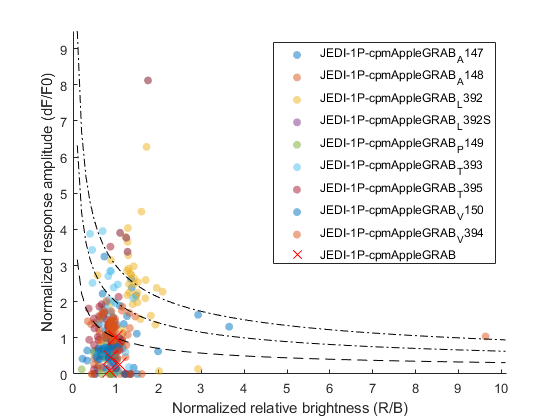

ctrlcolor = [1 0 0; 0 0 1];
i = 1; % Sheet 1
figure()
hold on
LibPos = unique(libApple(i).data.VarName);
libsel = [4:12]; 
ctrlsel = [3];
maxB = 0;
selrange = [];
for l = 1:length(libsel)
    librange = find(cellfun(@(x)~isempty(strfind(x,LibPos{libsel(l)})), libApple(i).data.VarName));
    scatter(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(librange),libApple(i).data.Normalized20ms(librange),'filled','MarkerFaceAlpha',0.5);
    maxB = max(maxB,max(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(librange)));
    selrange = [selrange;librange];
end

for c = 1:length(ctrlsel)
    ctrlrange = find(cellfun(@(x)~isempty(strfind(x,LibPos{ctrlsel(c)})), libApple(i).data.VarName));
    plot(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange),libApple(i).data.Normalized20ms(ctrlrange),'rx','MarkerSize',15);
    maxB = max(maxB,max(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange)));
    selrange = [selrange;ctrlrange];
end

x = 0:0.1:maxB+0.5;
DI1 = 1./sqrt(x);
DI2 = 2./sqrt(x);
DI3 = 3./sqrt(x);
plot(x,DI1,'--k')
plot(x,DI2,'-.k')
plot(x,DI3,'-.k')
legend(LibPos([libsel,ctrlsel]))
xlabel('Normalized relative brightness (R/B)')
ylabel('Normalized response amplitude (dF/F0)')
axis([0,maxB+0.5,0,inf])

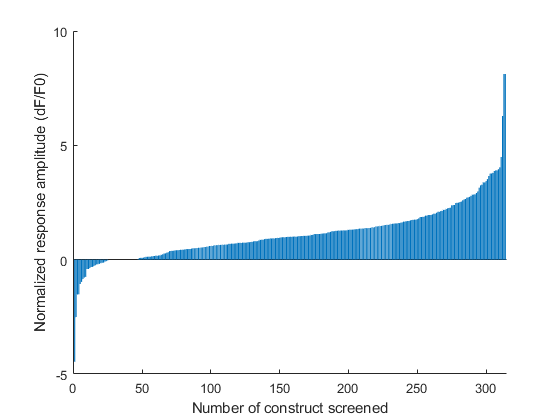


figure()
hold on
Normdff0_1 = libApple(i).data.Normalized20ms(selrange);
% Normdff0 = Normdff0(Normdff0>=0);
bar(sort(Normdff0_1,'ascend'))
xlabel('Number of construct screened')
ylabel('Normalized response amplitude (dF/F0)')

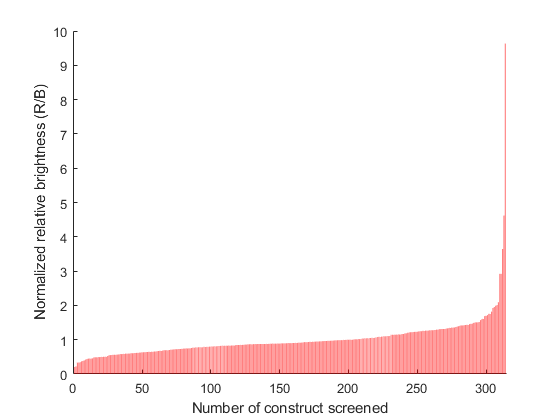


figure()
hold on
NormBr_1 = libApple(i).data.NormalizedBrightness_Ch2_Ch3_(selrange);
% NormBr = NormBr(NormBr>=0);
bar(sort(NormBr_1,'ascend'),'r','FaceAlpha',0.5)
xlabel('Number of construct screened')
ylabel('Normalized relative brightness (R/B)')

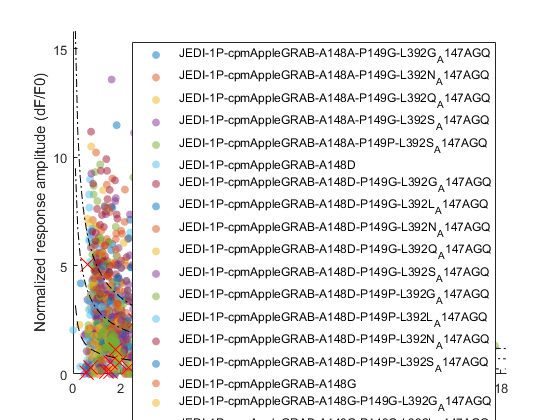

ctrlcolor = [1 0 0; 0 0 1];
i = 2; % Sheet 1
figure()
hold on
LibPos = unique(libApple(i).data.VarName);
libsel = [4:64]; 
ctrlsel = [3];
maxB = 0;
selrange = [];
for l = 1:length(libsel)
    librange = find(cellfun(@(x)~isempty(strfind(x,LibPos{libsel(l)})), libApple(i).data.VarName));
    scatter(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(librange),libApple(i).data.Normalized20ms(librange),'filled','MarkerFaceAlpha',0.5);
    maxB = max(maxB,max(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(librange)));
    selrange = [selrange;librange];
end

for c = 1:length(ctrlsel)
    ctrlrange = find(cellfun(@(x)~isempty(strfind(x,LibPos{ctrlsel(c)})), libApple(i).data.VarName));
    plot(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange),libApple(i).data.Normalized20ms(ctrlrange),'rx','MarkerSize',15);
    maxB = max(maxB,max(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange)));
    selrange = [selrange;ctrlrange];
end

x = 0:0.1:maxB+0.5;
DI1 = 1./sqrt(x);
DI2 = 3./sqrt(x);
DI3 = 5./sqrt(x);
plot(x,DI1,'--k')
plot(x,DI2,'-.k')
plot(x,DI3,'-.k')
legend(LibPos([libsel,ctrlsel]))
xlabel('Normalized relative brightness (R/B)')
ylabel('Normalized response amplitude (dF/F0)')
axis([0,maxB+0.5,0,inf])

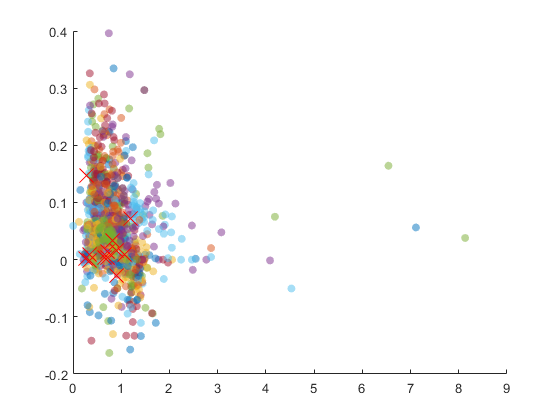


figure()
hold on
maxB = 0;
selrange = [];
for l = 1:length(libsel)
    librange = find(cellfun(@(x)~isempty(strfind(x,LibPos{libsel(l)})), libApple(i).data.VarName));
    scatter(libApple(i).data.RatioOfMeanBrightness_C2_C3_(librange),libApple(i).data.x20ms(librange),'filled','MarkerFaceAlpha',0.5);
    maxB = max(maxB,max(libApple(i).data.RatioOfMeanBrightness_C2_C3_(librange)));
    selrange = [selrange;librange];
end

for c = 1:length(ctrlsel)
    ctrlrange = find(cellfun(@(x)~isempty(strfind(x,LibPos{ctrlsel(c)})), libApple(i).data.VarName));
    plot(libApple(i).data.RatioOfMeanBrightness_C2_C3_(ctrlrange),libApple(i).data.x20ms(ctrlrange),'rx','MarkerSize',15);
    maxB = max(maxB,max(libApple(i).data.RatioOfMeanBrightness_C2_C3_(ctrlrange)));
    selrange = [selrange;ctrlrange];
end

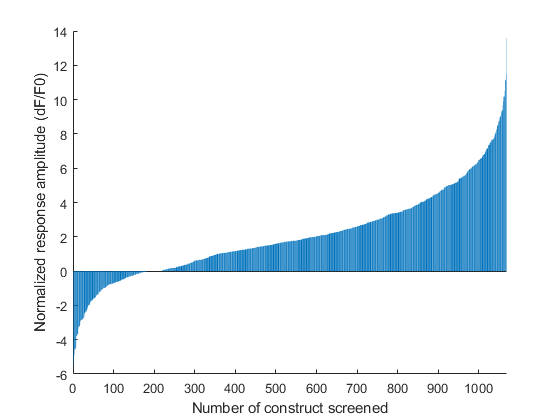


figure()
hold on
Normdff0 = libApple(i).data.Normalized20ms(selrange);
% Normdff0 = Normdff0(Normdff0>=0);
bar(sort(Normdff0,'ascend'))
xlabel('Number of construct screened')
ylabel('Normalized response amplitude (dF/F0)')

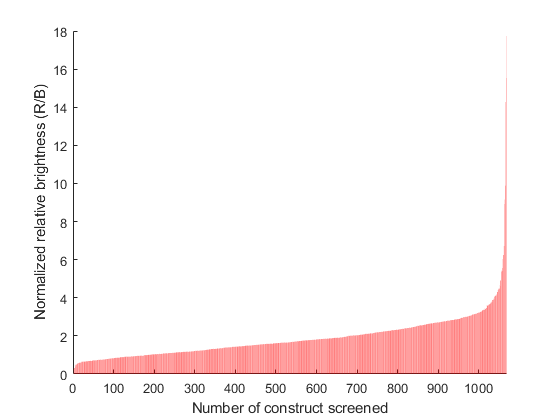


figure()
hold on
NormBr = libApple(i).data.NormalizedBrightness_Ch2_Ch3_(selrange);
% NormBr = NormBr(NormBr>=0);
bar(sort(NormBr,'ascend'),'r','FaceAlpha',0.5)
xlabel('Number of construct screened')
ylabel('Normalized relative brightness (R/B)')

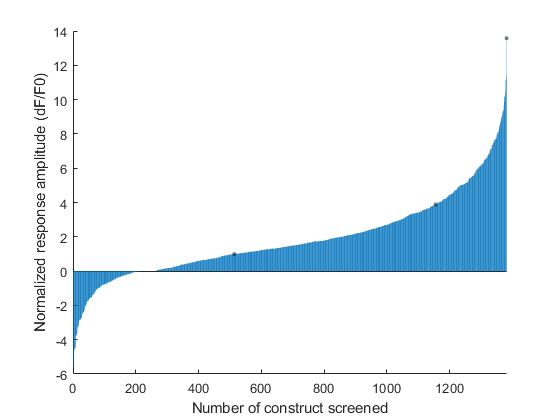

ctrlsel = [54,59];
L392S = [];
for c = 1:length(ctrlsel)
    ctrlrange = find(cellfun(@(x)~isempty(strfind(x,LibPos{ctrlsel(c)})), libApple(i).data.VarName));
    maxB = max(maxB,max(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange)));
    L392S = [L392S;ctrlrange];
end
Normdff0_L392S = mean(libApple(i).data.Normalized20ms(L392S));

ctrlsel = [3];
GRABctrl = [];
for c = 1:length(ctrlsel)
    ctrlrange = find(cellfun(@(x)~isempty(strfind(x,LibPos{ctrlsel(c)})), libApple(i).data.VarName));
    maxB = max(maxB,max(libApple(i).data.NormalizedBrightness_Ch2_Ch3_(ctrlrange)));
    GRABctrl = [GRABctrl;ctrlrange];
end
Normdff0_GRABctrl = mean(libApple(i).data.Normalized20ms(GRABctrl));
figure()
hold on
mAppledFF0 = sort([Normdff0_1;Normdff0],'ascend');
bar(mAppledFF0)
xlabel('Number of construct screened')
ylabel({'Normalized response';'amplitude (dF/F0)'})
scatter(514,1,10,'black','filled',"MarkerFaceAlpha",0.5)
scatter(1156,Normdff0_L392S,10,'black','filled',"MarkerFaceAlpha",0.5)
scatter(length(mAppledFF0),mAppledFF0(end),10,'black','filled',"MarkerFaceAlpha",0.5)

% Interactive scatter


## Load traces


sheet = {'Trace'};
Trace = readtable(fullfile(dirpath,fName),'Sheet',sheet{1});


figure()
subplot(1,3,1)
hold on
plot(Trace.Var3(1:360),Trace.mAppleGRAB(1:360),'Color',[0.9290, 0.6940, 0.1250])
plot(Trace.Var3(361:end),Trace.mAppleGRAB(361:end),'Color',[0.8500, 0.3250, 0.0980])
axis([0 3.5 -0.1 0.75])
axis square
xlabel('Time/s')
ylabel('dF/F0')
title({'JEDI-mAppleGRAB ';'(parent)'})
legend('1ms','20ms')

subplot(1,3,2)
hold on
plot(Trace.Var3(1:360),Trace.mApple1_0(1:360),'Color',[0.9290, 0.6940, 0.1250])
plot(Trace.Var3(361:end),Trace.mApple1_0(361:end),'Color',[0.8500, 0.3250, 0.0980])
axis([0 3.5 -0.1 0.75])
axis square
xlabel('Time/s')
ylabel('dF/F0')
title('JEDI-mApple 1.0')
legend('1ms','20ms')

subplot(1,3,3)
hold on
plot(Trace.Var3(1:360),Trace.mApple2_0(1:360),'Color',[0.9290, 0.6940, 0.1250])
plot(Trace.Var3(361:end),Trace.mApple2_0(361:end),'Color',[0.8500, 0.3250, 0.0980])
axis([0 3.5 -0.1 0.75])
axis square
xlabel('Time/s')
ylabel('dF/F0')
title('JEDI-mApple 2.0')
legend('1ms','20ms','location','best')

f = figure 
aH = axes;
 lH(1) = plot(aH,rand(10,1),'bs');
 hold on
 lH(2) = plot(aH,rand(10,1),'ro');
 lH(3) = plot(aH,rand(10,1),'k+');
 lH(4) = plot(aH,rand(10,1),'g^'); % some lines
 set(lH,'hittest','off'); % so you can click on the Markers
 hold on; 
 set(aH,'ButtonDownFcn',@getCoord); % Defining what happens when clicking
 uiwait(f) %so multiple clicks can be used

 function getCoord(aH,evnt)
drawnow
f = ancestor(aH,'figure');
click_type = get(f,'SelectionType');
ptH = getappdata(aH,'CurrentPoint');
delete(ptH)
if strcmp(click_type,'normal')
    %Finding the closest point and highlighting it
    lH = findobj(aH,'Type','line');
    minDist = realmax;
    finalIdx = NaN;
    finalH = NaN;
    pt = get(aH,'CurrentPoint'); %Getting click position
    for ii = lH'
        xp=get(ii,'Xdata'); %Getting coordinates of line object
        yp=get(ii,'Ydata');
        dx=daspect(aH);      %Aspect ratio is needed to compensate for uneven axis when calculating the distance
        [newDist idx] = min( ((pt(1,1)-xp).*dx(2)).^2 + ((pt(1,2)-yp).*dx(1)).^2 );
        if (newDist < minDist)
            finalH = ii;
            finalIdx = idx;
            minDist = newDist;
        end
    end
    xp=get(finalH,'Xdata'); %Getting coordinates of line object
    yp=get(finalH,'Ydata');
    ptH = plot(aH,xp(finalIdx),yp(finalIdx),'k*','MarkerSize',20);
    setappdata(aH,'CurrentPoint',ptH);

elseif strcmp(click_type,'alt')
    %do your stuff once your point is selected   
    disp('Done clicking!');
    % HERE IS WHERE YOU CAN PUT YOUR STUFF
    uiresume(f);
end
 end
 
